# **Exercise 1 – Global Positioning Systems (GPS)**

© Björn Åstrand, v7d

*Student(s): Your name(s) here!*

## Introduction

This exercise is about one of the essential sensors for outdoor applications, i.e. the Global Positioning Systems (GPS) sensor. This sensor is seen in more applications each day and is used for navigating, e.g. cars, ships and aeroplanes. This exercise consists of two sets of data, the first set' gps_ex1_window.txt', a series of GPS positions taken in the exact location, i.e. the GPS doesn't move (static receiver). The other data set, 'gps_ex1_morningdrive.txt', consists of data collected during a regular drive by car within Halmstad. A map of Halmstad is also included as the image file 'halmstad_drive_area.gif'.  Use the papers (that dealt with GPS data) handed out in the lectures.

## Matlab – quick help

Almost all the commands in Matlab contain help on how the commands should be called, how they work and what they return. To get help, simply write help followed by the command, e.g. to get help on plotting, write: `help plot`. To search for specific topics, i.e. in case you don't know the command name exactly, write lookfor followed by what to look for, e.g. looking for plotting commands could be done by writing: `lookfor plot`. 

If you are not familiar with Matlab, you should do a Tutorial found on Matlab home page.  

## Stationary GPS receiver 

Use the data set ‘gps_ex1_window.txt’ (simply write `DATA = load(‘gps_ex1_window.txt’`) in Matlab), which consists of time stamps and status flags together with values for longitudes and latitudes (given in NMEA-0183), i.e. the data file looks like:

`Status(1) Timestamp(1) Latitude(1) Longitude(1)`

`Status(2) Timestamp(2) Latitude(2) Longitude(2)`

`...`

`Status(N) Timestamp(N) Latitude(N) Longitude(N)`

To extract the Latitude and Longitude data from the variable DATA you can simply write `Longitude = DATA(:,4) and Latitude`  `= DATA(:,3).`

The "`:`" means that all rows in the given column (i.e. 3 or 4) are put in the new variable. Note that `Longitude` and `Latitude` are vectors and that in Matlab, you can do operations on vectors!

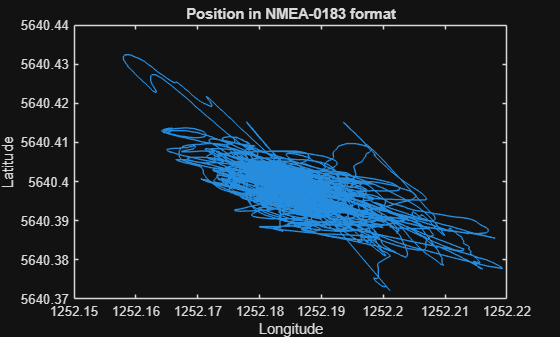

DATA = load('gps_ex1_window.txt');
Longitude = DATA(:,4); % read all rows in column 4
Latitude  = DATA(:,3); % read all rows in column 3
figure, plot(Longitude,Latitude);
title('Position in NMEA-0183 format');
xlabel('Longitude');
ylabel('Latitude');

### Write a function that transforms your longitude and latitude angles from NMEA-0183 into meters

This transformation includes two steps:

#### Transformation into degrees

Write a function that transforms your longitude and latitude angles from NMEA-0183 into degrees (use the first equation on the second page of the compendium, i.e. [http://adamchukpa.mcgill.ca/web_ssm/web_GPS.html](http://adamchukpa.mcgill.ca/web_ssm/web_GPS.html)).  Note: Square brackets mean integer of a value inside. In Matlab you can use the `floor` function to take the integer part of the value, i.e. truncation. Your code can look something like this:

`LongDeg = floor(Longitude/100) + (Longitude - floor(Longitude/100)*100)/60;`

`LongDeg`  is a vector containing the angles in degrees only. To look at the ten first values of `LongDeg` write `LongDeg(1:10)` and the ten last values, write `LongDeg(end-10:end).`

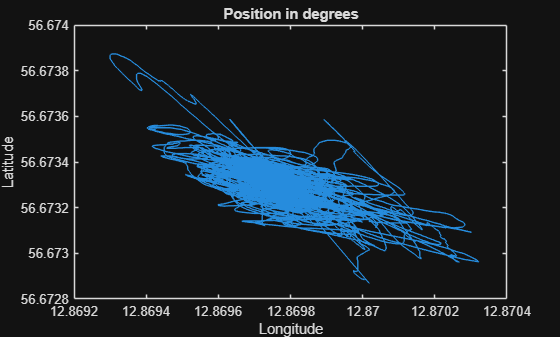

% LongDeg = 0;% = floor(Longitude/100) + (Longitude - floor(Longitude/100)*100)/60;
% LatDeg = 0; % 

LongDeg = floor(Longitude / 100) + (Longitude - floor(Longitude / 100) * 100) / 60;
LatDeg = floor(Latitude / 100) + (Latitude - floor(Latitude / 100) * 100) / 60;

figure, plot(LongDeg,LatDeg);
title('Position in degrees');
xlabel('Longitude');
ylabel('Latitude');

#### Transform degrees into meters 

Then, transform from degrees into meters (use the conversion tables given at the end of the compendium, [http://adamchukpa.mcgill.ca/web_ssm/web_GPS_tb.html](http://adamchukpa.mcgill.ca/web_ssm/web_GPS_tb.html). Assume height zero and latitude of 56 degrees.) in a coordinate system with the x-axis on the Equator and the y-axis passing Greenwich. Your code can look something like this:

`X = F_lon * LongDeg;`

Don't forget to plot your results using: `plot(X,Y,'.');` To plot in a new figure use: `figure, plot(X,Y,'.');`

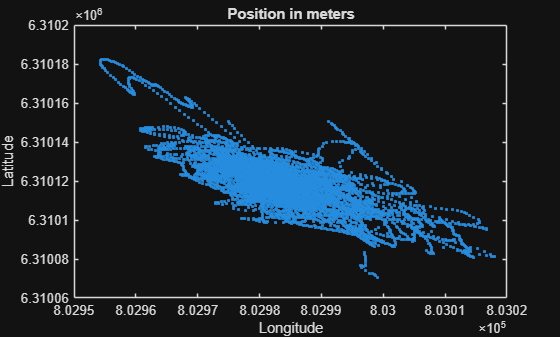

F_lon = 62393; % from table
F_lat = 111342; % from table


X = F_lon * LongDeg;
Y = F_lat * LatDeg;

figure, plot(X,Y,'.');
title('Position in meters');
xlabel('Longitude');
ylabel('Latitude');

### Estimate the mean and variance of the position (in x and y)

To calculate the position error, we must know the actual position. Since we don't know that, we have to estimate the true value. We do that by calculating the mean of all values: `Error_X = X - mean(X);`

Calculate the covariance matrix of the errors in the x and y position data, i.e. in Matlab, simply write cov`([X Y])` if you have the errors stored in Error_X and Error_Y as [N x 1] vectors. Plot the covariance matrix in the same 2D plot where you plotted the errors, but use a different colour, e.g. red. Use the function plot_uncertainty2(…), called by e.g.: `plot_uncertainty2([0 0]', cov([X Y]), 1, 2,'r')`, which then plots the covariance matrix centred around (0, 0). To plot in the same figure use: `hold on`;

Plot the position errors (mark each error with an '.') in a 2D plot. Test to plot different fractions of the signal, e.g. `plot(Error_X(1:10), Error_Y(1:10),'r.')`or` plot(Error_X(101:110), Error_Y(101:110),'r.')`. Compare with random points generated with the same variance as the GPS error: c = cov([X Y]);  `yr = randn(1,10)*sqrt(c(4));xr = randn(1,10)*sqrt(c(1));` `plot(xr,yr,``'r*'``);`

Error_X = X-mean(X); % -> Your code here
Error_Y = Y-mean(Y); % -> Your code here
figure, plot(Error_X, Error_Y); hold on;

C = cov([X Y]);

% -> Your code here for plot plot_uncertainty()
plot_uncertainty2([0 0]', C, 1, 2,'r');
hold on;

% Plot fractions here
plot(Error_X(101:110), Error_Y(101:110),'r.');

% plot random points here
xr = randn(1,10)*sqrt(C(1));
yr = randn(1,10)*sqrt(C(4)); 
plot(xr,yr,'r*');

grid on;
title('Position in meters');
xlabel('Longitude');
ylabel('Latitude');

**Q1: What is the maximum error? Mark in the figure by: plot(...,...,'ro');**

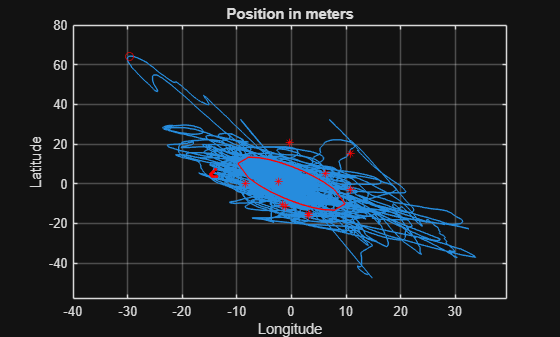

% -> Your code here
d = sqrt(Error_X.^2 + Error_Y.^2); 
[a, b] = max(d); % a is the max distance and b is the index at which it occur
plot(Error_X(b), Error_Y(b), 'ro');

**Q2:Can you say something about the GPS errors? What is the difference between the GPS and the randomly generated points? Reason about the difference in spatial-temporal behaviour in the figure above. **

**Ans 1 : GPS error are the actual real sensor errors that produces smooth, and slowly varrying spatial offset. In short these are the realistic sensor noise.**

**Ans 2 : GPS error are magnitude-limited and temporily correlated while randomly generated errors are independent, identically distributed white noise.  Moreover, GPS error looks smoother and show slow bias whereas randm error appears as time-independent scatter with no memory. **

**Ans 3: **

**Q3: Are the errors Gaussian distributed? (To check this, plot, using **`histogram(…)`**, a histogram over the errors. Use at least 30 bins). **

% -> Your code here

### Plot with respect to time the errors and the auto-correlation in x and y separately.

Plot, with respect to time, the errors in x and y separately – (use Matlab's function of creating subplots, i.e. write `subplot(4,1,1); plot(Error_X), subplot(4,1,2); plot(Error_Y);` etc.) 

Also plot the auto-correlation of the errors in x and y respectively. Call the function `xcorr(…)` and calculate the auto-correlations according to the following: `cx = xcorr(Error_X, ‘coeff’);` and `cy = xcorr(Error_Y, ‘coeff’);` Plot the auto-correlations (`cx` and `cy`) in subplots 3 and 4. Also, generate a random signal using following: `R = randn(1,length(Error_X))`, that generates a random signal of the same length as `X`. Do the auto-correlation on this signal and plot it in subplots 3 and 4 using the `hold `command, i.e. `cn = xcorr(R - mean(R), 'coeff'); subplot(4,1,3); hold on; plot(cn,' r');` 

% -> Your code here


**Q4: Do you find any interesting with the errors (Subplot 1 and 2)? **

**Q5: Compare the random (Gaussian) signal with the GPS-error (Subplot 3 and 4).  What is the difference? **

**Q6: Are the GPS error correlated in time or not? See the result of the auto-correlation? For how many samples are the GPS error 90% similar? You need to zoom in around the peak to see the difference.**

**Q7: How does this affect your position measurements? Reason about the short-term (about 10 samples) and long-term (the whole data set) precision and accuracy of the GPS measurements. **

**Q8: Compare when you plot parts of the GPS-error signal in the position plot above, i.e. what does it mean that the peak in the auto-correlation plot is wider than the random signal? **

## Mobile GPS receiver

Use the data set 'gps_ex1_morningdrive.txt', which is collected during a drive on the eastern side of Halmstad. Also, see the map of Halmstad and see if you can locate where in Halmstad the drive took place.

### Plot the position data

Plot the position data (x and y) in the same plot, which should give you the path taken by the car (this path is the same path I showed you in the lectures). 

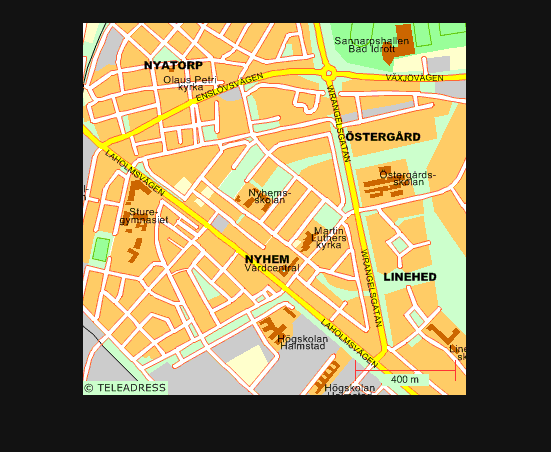

[Img,map] = imread('halmstad_drive_area.gif');
figure, imshow(Img,map);DATA = load('gps_ex1_morningdrive.txt');

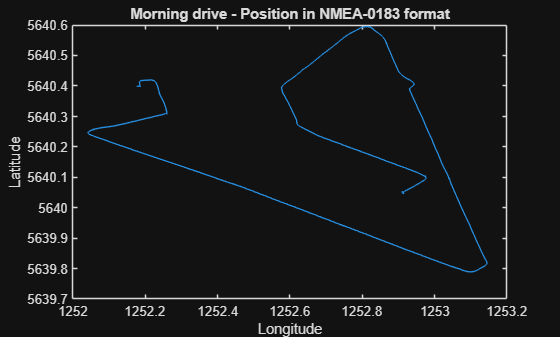

Longitude = DATA(:,4); % read all rows in column 4
Latitude  = DATA(:,3); % read all rows in column 3
figure, plot(Longitude,Latitude);
title('Morning drive - Position in NMEA-0183 format');
xlabel('Longitude');
ylabel('Latitude')

### Plot the speed data

First you need to convert to meter as above.

% -> Your code here

**Q9: Calculate the maximum speed taken by the driver. Note: In Matlab, you can do element vice operations, e.g. multiplication, like **`x.*x`** instead of vector operation **`x*x. `**In the speed plot, mark the where the maximum speed occurs. Also, in the Morning Drive plot above, mark the position where the maximum speed occurs.** **To calculate dx you can use the function diff(), i.e. dx = diff(x);**

% -> Your code here

**Q10: Did I ever break the speed limits, i.e. 70 km/h? **

% -> Your code here

**Q11: How come the estimate in speed is so accurate while the estimate in position is not? This is very important! Recall what you find out about the GPS error in the first part of the exercise. Note that the speed is in this exercise calculated as the differance between two points divided by time (Q9).**

### Plot the headings

Calculate the headings (and plot them with respect to time) along the path (see compendium [http://adamchukpa.mcgill.ca/web_ssm/web_GPS.html](http://adamchukpa.mcgill.ca/web_ssm/web_GPS.html)). Note that the the matlab function **atan2d() **can be used here instead of the "if statments"  in the compendium. 

**Q12: Can you calculate the error in headings? Tips! If you only consider the headings along the straight-line path (along Laholmsvägen or Vrangelsleden) – can you then estimate the variance in the heading? **

% -> Your code here. Plot all headings!

Mark the heading values used for calculating the heading variance in the heading plot. Also, mark the positions used for the heading calculation in the Morning drive plot above. Tips use the data points between 240:315.

% -> Your code here

## **Submitt your exercise**

The reports shall be handed in via Blackboard. All questions shall be answered properly, and elaborated figures shall be included. Submitt both the .mlx file and aslo save it as a PDF file, Submitt it as two separat files in Blackboard. Don't forgett to add your name(s) at the top of the document.

## **References**

[1] W. Lechner and S. Baumann, Global Navigation Satellite Systems, Computers and Electronics in Agriculture, Volume 25, Issues 1-2, January 2000, Pages 67-85.

[https://doi.org/10.1016/S0168-1699(99)00056-3](https://doi.org/10.1016/S0168-1699(99)00056-3)

[2] Adamchuk, Viacheslav I., "EC01-157 Precision Agriculture: Untangling the GPS Data String" (2001). Historical Materials from University of Nebraska-Lincoln Extension. Paper 707.

[https://www.researchgate.net/profile/Viacheslav_Adamchuk/publication/228382384_EC01-157_Precision_Agriculture_Untangling_the_GPS_Data_String/links/54ba7fbf0cf253b50e2d0234.pdf?origin=publication_list](https://www.researchgate.net/profile/Viacheslav_Adamchuk/publication/228382384_EC01-157_Precision_Agriculture_Untangling_the_GPS_Data_String/links/54ba7fbf0cf253b50e2d0234.pdf?origin=publication_list)